# Dribble Analysis

## Perfoming fourier analysis

We're going to look at standard dribbling

dribble = load("Basketball/SensorData/d4.mat");

d_a = dribble.Acceleration

d_a = 96×3 timetable
           Timestamp              X          Y           Z   
    ________________________    ______    ________    _______

    07-Dec-2019 16:46:34.127    7.1324      1.3187     6.7953
    07-Dec-2019 16:46:34.222     7.006      1.0788     6.7105
    07-Dec-2019 16:46:34.317     6.702      1.9234     6.6363
    07-Dec-2019 16:46:34.412    6.8614      1.5452       7.13
    07-Dec-2019 16:46:34.507    5.9646      2.6905     5.8855
    07-Dec-2019 16:46:34.602    5.3436      3.7894     5.8654
    07-Dec-2019 16:46:34.697    6.8365      3.2842     4.6425
    07-Dec-2019 16:46:34.792    10.275      2.9041     3.6633
    07-Dec-2019 16:46:34.887    10.557      2.1236     3.1395
    

Convert Timestamp into seconds

d_t = posixtime(d_a.Timestamp);
d_t = d_t - d_t(1)

d_t =          0
    0.0950
    0.1900
    0.2850
    0.3800
    0.4750
    0.5700
    0.6650
    0.7600
    0.8550


Plot z component acceleartion against time in seconds

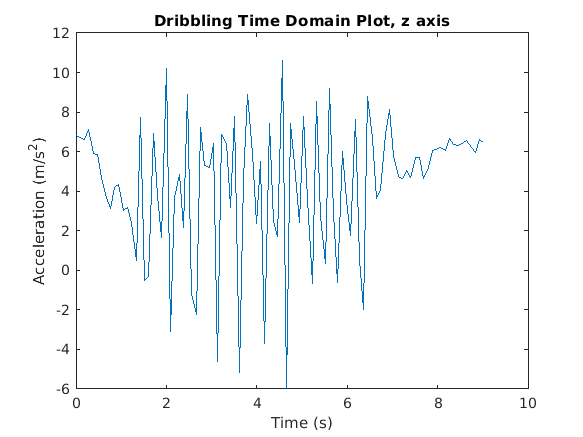

figure;
plot(d_t, d_a.Z);
title("Dribbling Time Domain Plot, z axis");
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");

Take the DFT of z component accelration signal

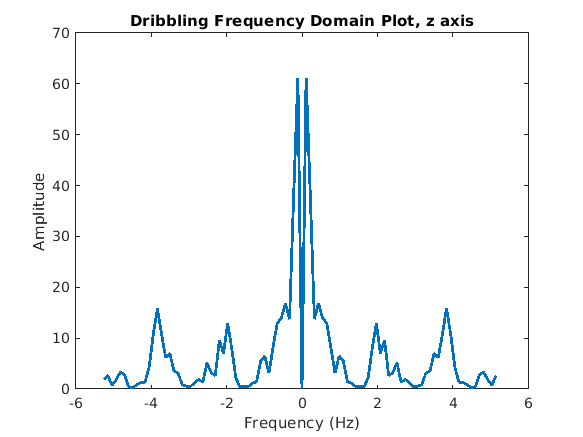

d_azFiltered = movmean(d_a.Z, 7);

fig = figure;
N = length(d_azFiltered);
Fs = 1/(d_t(2)-d_t(1));
f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);

% Remove 0 frequency (artifact of FFT)
h = plot(f, abs(fftshift(fft(d_azFiltered - mean(d_azFiltered)))));
set(h,'LineWidth', 2);

xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Dribbling Frequency Domain Plot, z axis')

Take the DFT of x component accelration signal

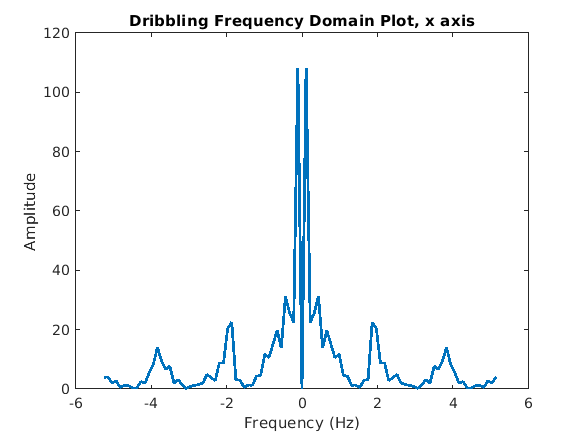

d_axFiltered = movmean(d_a.X, 7);

fig = figure;
N = length(d_axFiltered);
Fs = 1/(d_t(2)-d_t(1));
f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);

% Remove 0 frequency (artifact of FFT)
h = plot(f, abs(fftshift(fft(d_axFiltered - mean(d_axFiltered)))));
set(h,'LineWidth', 2);

xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Dribbling Frequency Domain Plot, x axis')

Get n most prominent peaks

n = 3;
[peaks, indices] = findpeaks(abs(fftshift(fft(d_axFiltered - mean(d_axFiltered)))))

peaks =     4.1009
    2.8115
    1.2296
    2.4885
   14.0451
    7.7031
    3.1971
    4.9229
    8.8177
   22.5469


indices =      2
     4
     6
    10
    14
    17
    19
    26
    29
    32


halfway = ceil(length(indices) / 2)

halfway = 15

[max, indexes] = maxk(peaks(1:halfway),n)

max =   108.3608
   31.2659
   22.5469


indexes =     15
    14
    10


freq = [];
amp = [];
for i = 1:n
    freq = [freq -f(indices(indexes(i)))];
    amp = [amp max(i)];
end
freq

freq =     0.1096    0.4386    1.8640


amp

amp =   108.3608   31.2659   22.5469
